clc; clear all; close all;

**Task 2: Find parameter solutions for the following scenario**

**Scenario 1:** The system exhibits stable oscillations with a periodicity of approximately 70 months.

**Simulation settings:**

**Timespan**: In all scenarios, simulate from 0 to 200 months.

t0 = 0;                 	% Start time of simulation [in months]
tfinal = 200;               % End time of simulation [in months]
tspan = [t0 tfinal];        % Time span defined by the start and end times of the simulation [in months]

**Initial population sizes:**

y0 = [0.751 0.2 0.715]  % Initial state [plants hares lynx] at t=0, between 0.1-10 for each

y0 =     0.7510    0.2000    0.7150


**Parameter values:**

a1 = 5                      % Hare predation success rate ("how likely the plant dies if it meets a hare"), between 1-10

a1 = 5

b1 = 5                      % Hare population growth rate due to predation on plants ("how much food a hare gets out of eating plants"), between 1-10

b1 = 5

d1 = 0.6                   % Hare per capita death rate, between 0.1-1

d1 = 0.6000


a2 = 0.5                    % Lynx predation success rate ("how likely the hare dies if it meets a lynx"), between 0.1-1

a2 = 0.5000

b2 = 1.9                      % Lynx population growth rate due to predation on hares ("how much food a lynx gets out of eating hares"), between 1-10

b2 = 1.9000

d2 = 0.06                   % Lynx per capita death rate, between 0.01-1

d2 = 0.0600

**Model simulation**

[t,y] = ode45(@(t,y) plants_hare_lynx(t,y,a1,a2,b1,b2,d1,d2), tspan, y0);  % Simulation of the Plant-Hare-Lynx 3-species model

**Population over time plot**

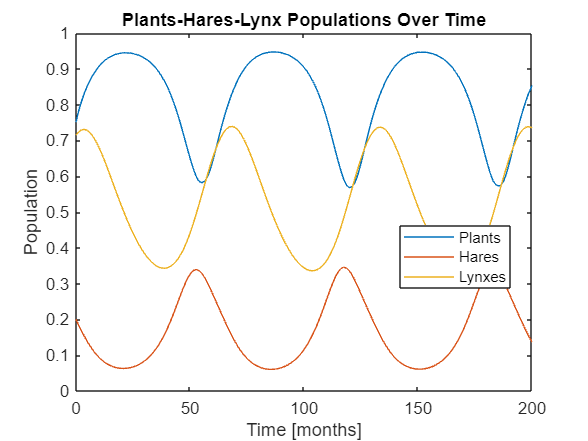

figure("Name",'Plants-Hares-Lynx')
plot(t,y)
title('Plants-Hares-Lynx Populations Over Time')
xlabel('Time [months]')
ylabel('Population')
legend('Plants','Hares','Lynxes','Location','Best')

**State space plot**

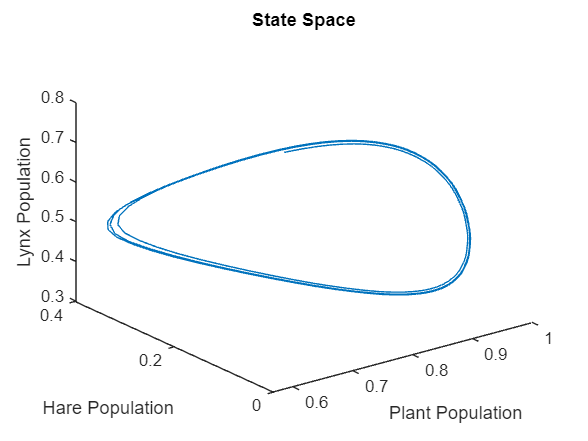

figure("Name",'State Space')
plot3(y(:,1),y(:,2),y(:,3));
title('State Space')
xlabel('Plant Population')
ylabel('Hare Population')
zlabel('Lynx Population')

function dydt = plants_hare_lynx(t,y,a1,a2,b1,b2,d1,d2)

dydt = zeros(3,1);

% y(1) is X, number of plants
% y(2) is Y, number of hares
% y(3) is Z, number of lynxes

dydt(1) = y(1)*(1-y(1)) - ((a1*y(1))/(1+b1*y(1)))*y(2); %Plants
dydt(2) = ((a1*y(1))/(1+b1*y(1)))*y(2)-d1*y(2)-(a2*y(2)/(1+b2*y(2)))*y(3); %Hares
dydt(3) = (a2*y(2)/(1+b2*y(2)))*y(3) - d2*y(3); %Lynxes

end
